## Classification of Iris Species

clear

### Importing the Data

The Iris data set contains two sets of variables - the *irisInputs* and the *irisTargets*. 

The *irisInputs* has 4 rows and 150 columns. The first 50 columns represent the first iris flower species, the *Iris-setosa*. The second 50 columns correspond to the species *Iris-versicolor*. The third set of 50 columns pertain to the species *Iris-virginica*. The first row correspond to the information about the sepal length (in cm), the second row about the sepal width (in cm), the third about the petal length (in cm), and the fourth the petal width (in cm). 

The *irisTargets* has 3 rows and 150 columns. The first 50 columns and first row with values of ones represent target values for the first iris flower species, the *Iris-setosa*. The next 50 columns and second row with values of ones represent target values for the first iris flower species, the *Iris-versicolor*. The last 50 columns and third row with values of ones represent target values for the first iris flower species, the *Iris-virginica*. 

load iris_dataset.mat
inputs = irisInputs
inputs = irisInputs
inputs = irisInputs
inputs = irisInputs
targets = irisTargets

### Displaying the Data in a Table

Display the data set in a table. For convenience in viewing, the data set is transposed. Because there are three classes (or species), the target must be a 3-row matrix.

iris = [irisInputs' irisTargets'];
table_iris = array2table(iris);
table_iris.Properties.VariableNames = {'Sepal Length (cm)',...
    'Sepal Width (cm)','Petal Length (cm)','Petal Width (cm)',...
    'Setosa','Versicolor','Virginica'}

### Representative Images of the 3 Iris Species

*Iris Setosa*

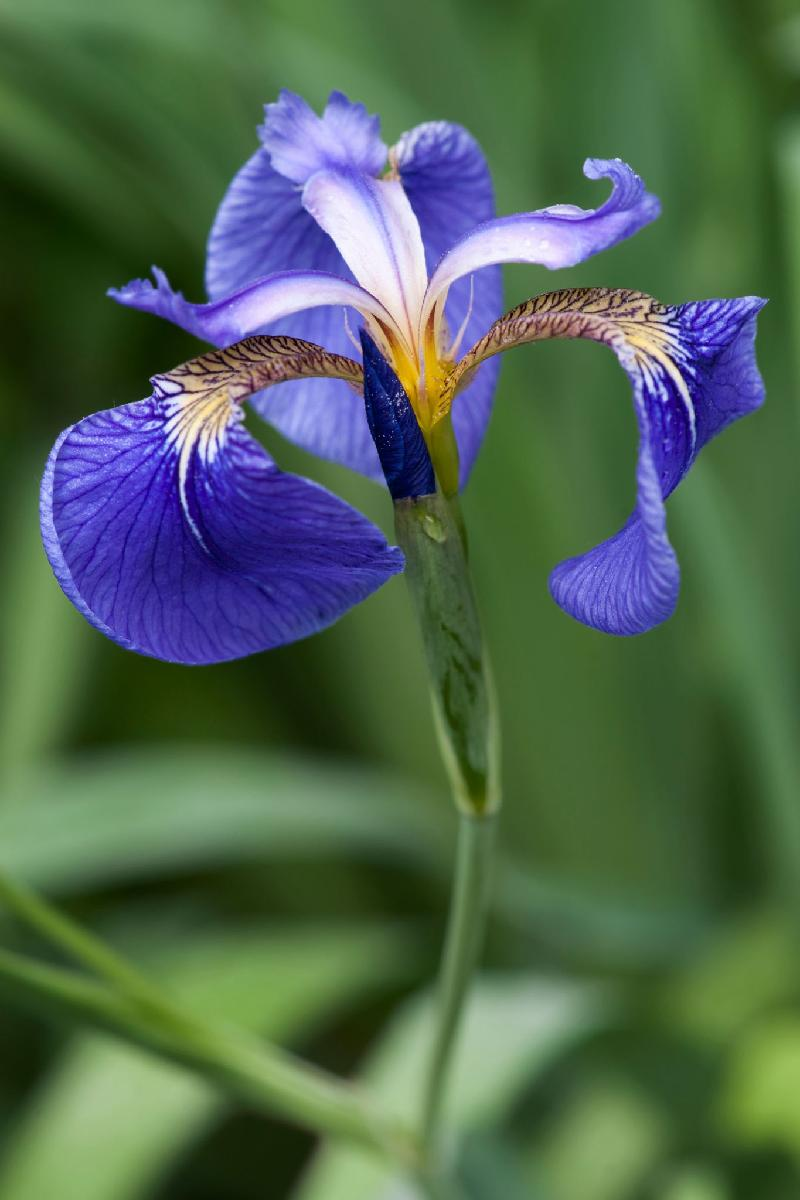

*Iris Versicolor*

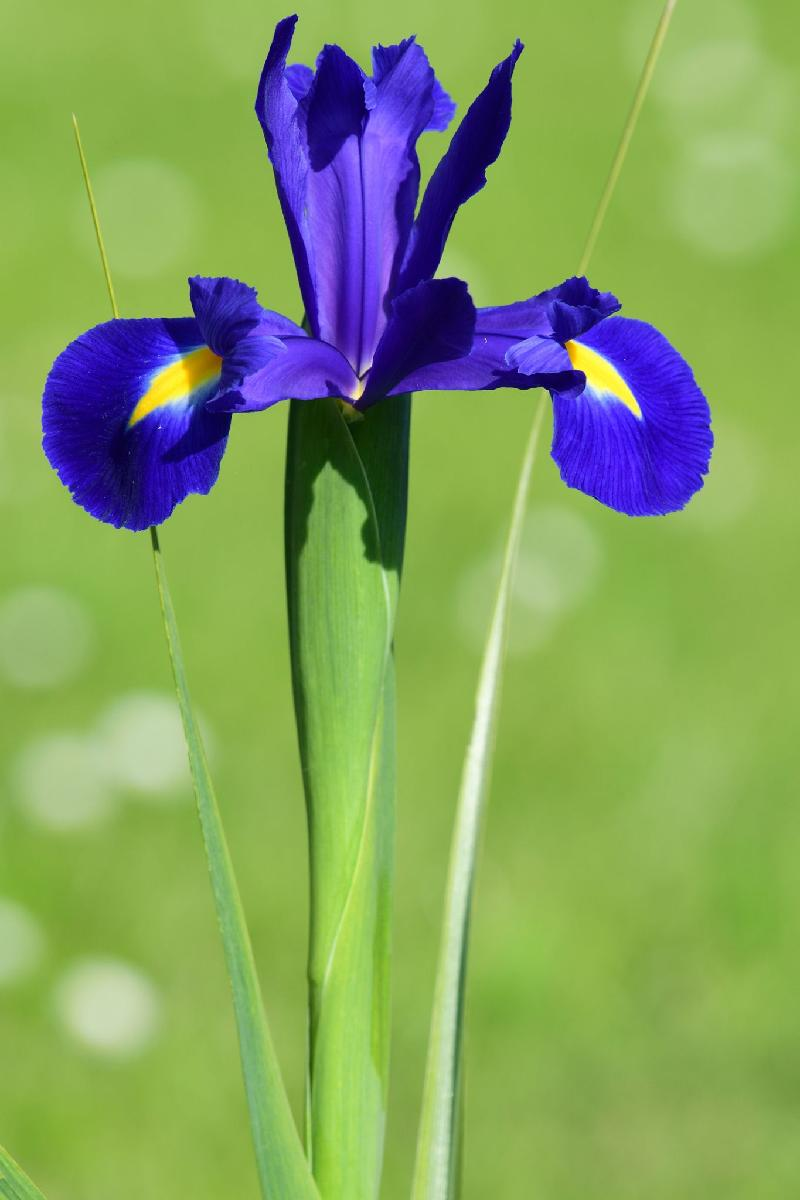

*Iris Virginica*

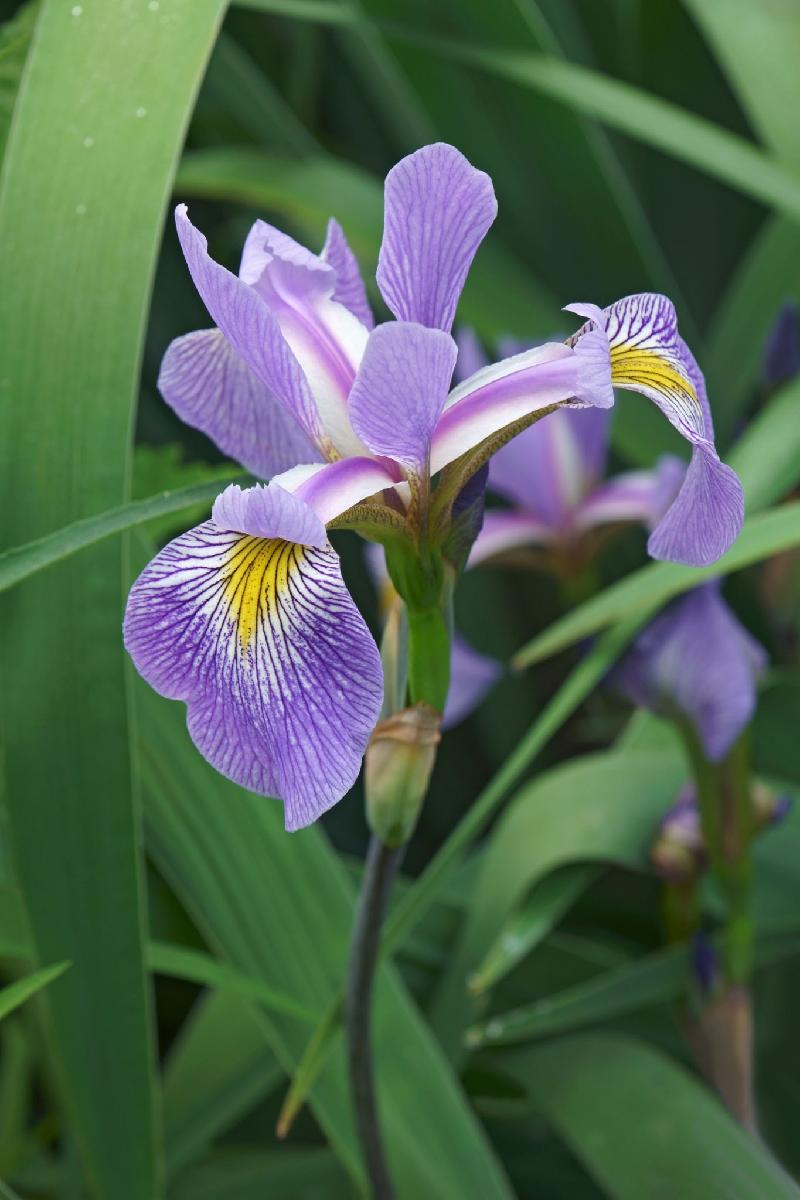

### Setting the Training Parameters

To train our network, we are going to use the function [patternnet](https://se.mathworks.com/help/deeplearning/ref/patternnet.html). This function generates a pattern recognition network.

Let's define the number of nodes in the hidden layer. There is only one hidden layer.

hiddenNodes = 4;

Then, we define the optimization function or the training function. MATLAB has a different set of [training functions](https://se.mathworks.com/help/deeplearning/ug/choose-a-multilayer-neural-network-training-function.html). Here we use the Levenberg-Marquardt optimization algorithm.

trainFcn = 'trainlm';

We generate the pattern recognition network with patternnet. The first argument is the number of nodes in the hidden layer. The second argument is the training function. The third is the performance function. The default is [crossentropy](https://se.mathworks.com/help/deeplearning/ref/crossentropy.html), but we'll change it to [mse](https://se.mathworks.com/help/deeplearning/ref/mse.html), since it's the one we are currently familiar with. To learn more about other performance functions, type 'help nnperformance' in the command window.

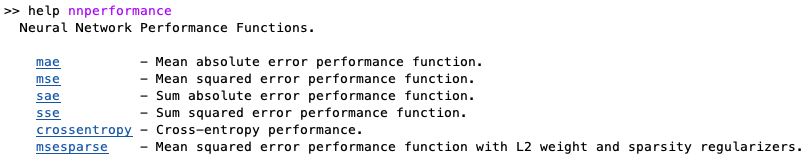

net = patternnet(hiddenNodes, trainFcn,'mse');

We now divide the data set to a training data, validation data and the test data. The training data is the data set used to train the model. The validation data is used during training at some iterations or epochs just to make a quick check whether the model is underfitting or overfitting or is just right. The test data is used after the training to check the accuracy of the model. 

In this case, we use 70% of the data set as the training data, 15% as the validation data, and the remaining 15% as the test data.

*divideParam* is an object property of the output variable *net*. Check out the other [Neural Network Object Properties](https://se.mathworks.com/help/deeplearning/ug/neural-network-object-properties.html).

The parameters *trainRatio*, *valRatio* and *testRatio* are sub-object properties of the parameter *divideParam*. Explore more [Neural Network Subobject Properties](https://se.mathworks.com/help/deeplearning/ug/neural-network-subobject-properties.html).

net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

Set the maximum number of epochs to 1000. The variable *epoch* is a subobject property of the object property *trainParam* of the output variable *net*. The training stops when this value is attained.

net.trainParam.epochs = 1000; 

Set the maximum validation failures to 500. The variable *max_fail* is a subobject property of the objecty property *trainParam* of the output variable *net*. The training stops when this value is attained.

net.trainParam.max_fail = 500;

Set the minimum performance gradient to 1e-15. The variable *min_grad* is a subobject property of the objecty property *trainParam* of the output variable *net*. The training stops when this value of the performance gradient falls below this value.

net.trainParam.min_grad = 1e-15;

Set the learning rate to 0.1. The variable *lr* is a subobject property of the objecty property *trainParam* of the output variable *net*. You can take a look at more subobject properties in the function [traingdx](https://se.mathworks.com/help/deeplearning/ref/traingdx.html).

net.trainParam.lr = 0.1;

We now select the transfer function or the activation function to be used for each layer. For the first layer, we select the sigmoid function. For the second layer, we select a linear activation function.

You can learn more about the various activation functions in MATLAB by typing 'help nntransfer' in the command window.

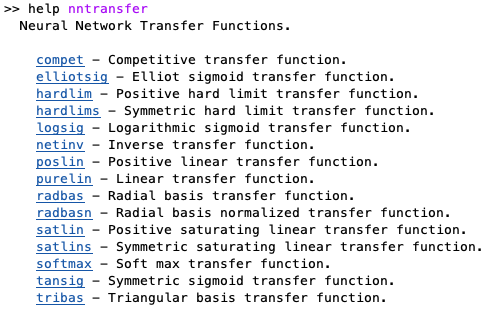

net.layers{1}.transferFcn='logsig';
net.layers{2}.transferFcn='purelin';

### Training the Data

Now, we train the network. This is achieved with the function [train](https://se.mathworks.com/help/deeplearning/ref/network.train.html). This function is used for shallow networks, i.e., for 1 or 2 hidden layers. The first argument is the model name, the second is the input parameter, and the third the target parameter. The output of the function is the model with the target properties and the training record.

[net, tr] = train(net,inputs,targets);

### Displaying the network diagram

Display the model *net*. For this example, the model should have 3 layers - the input layer with 4 nodes, the hidden layer with 4 nodes, and the output layer with 3 nodes. Notice that the hidden layer displays the type of activation function used. 

view(net)

### Displaying the weights and biases

net.IW{1} %the input-to-hidden layer weights
net.LW{2} %the hidden-to-output layer weights
net.b{1}  %the input-to-hidden layer bias
net.b{2}  %the hidden-to-output layer bias

### Evaulating the Performance

Display the performance of the training using the [perform](https://se.mathworks.com/help/deeplearning/ref/network.perform.html) function. The output of this function is the 'mse', which you set in the model net using the patternnet function.

outputs = net(inputs);
performance = perform(net,targets,outputs);

The accuracy can be determined using the confusion matrix with the [confusion](https://se.mathworks.com/help/deeplearning/ref/confusion.html) function. The output is the confusion value, which is the fraction of misclassified samples. The accuracy is computed from the confusion value, as shown.

[misclassified, cm, idx, percentages] = confusion(targets,outputs);
accuracy = 100 * (1 - misclassified);
fprintf('Accuracy = %.3f%%', accuracy);

We also display the confusion matrix to assess which parts were incorrectly classified.

confusionchart(cm)
plotconfusion(targets,outputs)
idx